# Modeling density of bird migration with temperature and wind

## 1. Import and create data

Note that you'll need the inference dataset generated with `Inference.mlx`

clear all; addpath('./functions/'); warning('off')
load('../1-Cleaning/data/dc_corr.mat'); 
load('./data/Density_inference.mat','ampli','pow_a','res'); 
load('../6-Flight/data/Flight_inference.mat','data');

Define a few useful variable

dclat = [dc.lat]';
dclon = [dc.lon]';
data.denst = data.dens.^pow_a;
Gneiting = @(dist,time,range_dist,range_time,delta,gamma,beta) 1./( (time./range_time).^(2.*delta) +1 ) .* exp(-(dist./range_dist).^(2.*gamma)./((time./range_time).^(2.*delta) +1).^(beta.*gamma) );

Create the data structure `data` used for the rest of the code

data.temperature=nan(size(data,1),1);
data.windu=nan(size(data,1),1);
data.windv=nan(size(data,1),1);

One could test to interpolate wind profile vertically to weight the vertical average of wind according to the number of bird. (not done)

% press=950:-50:700;
% alt_pres = (1-(press*100/101325).^(1/5.25588))/2.25577/10^(-5);

for i_d=1:numel(dc)

    id = ismember(datenum(dc(i_d).time),data.time(data.radar==i_d));
    
%     % Test Interpolation with height
%     alt = (1:dc(i_d).levels).*dc(i_d).interval;
%     tmp=diff(double([0 max(0, alt - dc(i_d).height )]))/1000;
%     alt=alt-dc(i_d).interval/2;
%     [2 alt_pres] 
%     [dc(i_d).t2m(id) dc(i_d).t(id,:)]
    
    data.temperature(data.radar==i_d,:) = dc(i_d).t2m(id);
    data.windu(data.radar==i_d,:) = dc(i_d).u100(id);
    data.windv(data.radar==i_d,:) = dc(i_d).v100(id);
end

We tested two measure of wind support. One is tailwind (projection of wind vector on the flight speed vector) and meanflight (projection of wind vector on the average flight direction (~217°).

I will use meanwind because tailwind is changing and its correlation with density is not great. 

data.tailwind = sum([data.windu data.windu].*[data.u data.v],2) ./ sqrt(sum([data.u data.v].^2,2));
meanflight = sum([data.u data.v].*data.dens)/sum(data.dens);
data.meanwind = sum([data.windu data.windu].*meanflight,2) ./ sqrt(sum(meanflight.^2,2));

## 2. Amplitude

Compute average amplitude for density, temperature and wind

ampli.A =nan(numel(ampli.r), numel(ampli.t),3);
for i_r=1:size(ampli.A,1)
    for i_t=1:size(ampli.A,2)
        id = data.radar==i_r & data.day==i_t;
        ampli.A(i_r,i_t,:)=[mean(data.denst(id)) -mean(data.temperature(id)) mean(data.meanwind(id))];
    end
end
ampli.isnan=isnan(ampli.A(:,:,1));

### 2.1 Trend

Illustrate trend presents

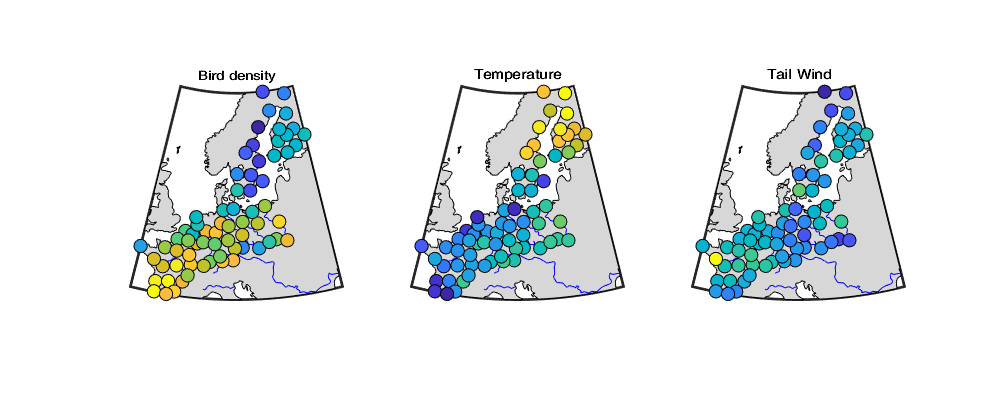

tt={'Bird density','Temperature','Tail Wind'};
figure('position',[0 0 1000 400]);
for i_v=1:size(ampli.A,3)
    subplot(1,3,i_v); h=worldmap([min(dclat) max(dclat)], [min(dclon) max(dclon)]);
    setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
    geoshow('landareas.shp', 'FaceColor', [215 215 215]./255); geoshow('worldrivers.shp','Color', 'blue')
    scatterm(dclat,dclon,100,nanmean(ampli.A(:,:,i_v),2),'filled','MarkerEdgeColor','k');title(tt(i_v))
end

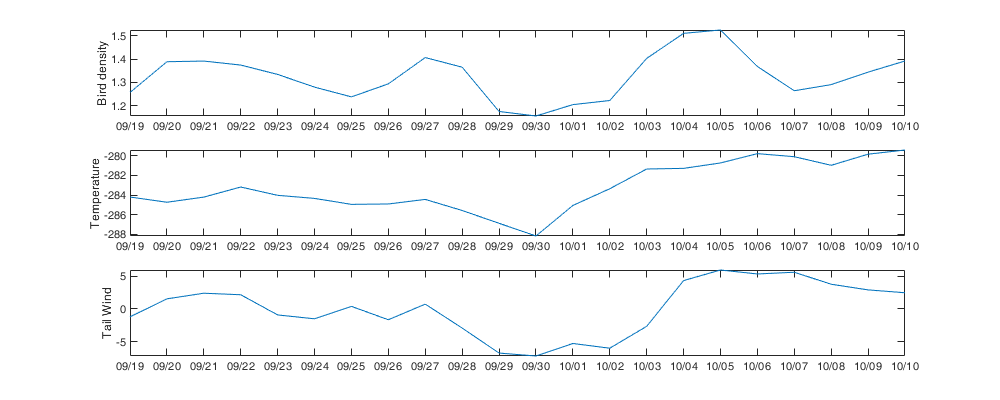

figure('position',[0 0 1000 400]); 
for i_v=1:size(ampli.A,3)
    subplot(size(ampli.A,3),1,i_v); plot(ampli.t,nanmean(ampli.A(:,:,i_v))); axis tight; datetick('x'); ylabel(tt(i_v))
end

Remove the spatial trend in all three variable plus standardize variable to all have a variance of one (everything works without, but easier to compare cross-covariance function).

ampli.An = nan(sum(sum(~ampli.isnan)),3);
for i_v=1:size(ampli.A,3)
    tmp = ampli.A(:,:,i_v);
    ampli.w(1:2,i_v) = [ones(sum(~ampli.isnan(:)),1) dclat(ampli.R(~ampli.isnan))] \ tmp(~ampli.isnan);
    tmp2 = tmp(~ampli.isnan)-dclat(ampli.R(~ampli.isnan))*ampli.w(2,i_v)-ampli.w(1,i_v);
    ampli.w(3,i_v) = std(tmp2(:));
    ampli.An(:,i_v) = tmp2(:) ./ ampli.w(3,i_v);
end

Parameters:

ampli.w

ans =     2.5141 -299.0060    2.5560
   -0.0224    0.2976   -0.0454
    0.1907    3.2951    5.7341


### 2.2. Covariance function

Buliding the distance matrix in time and space of the amplitude

Dtime=squareform(pdist(ampli.T(~ampli.isnan)));
Ddist=squareform(pdist([dclat(ampli.R(~ampli.isnan)) dclon(ampli.R(~ampli.isnan))],@lldistkm));

Compute the empirical covariance

for i_v1=1:size(ampli.A,3)
    for i_v2=1:size(ampli.A,3)
        cov_emp(:,:,i_v1,i_v2) = bsxfun(@times, ampli.An(:,i_v1)', ampli.An(:,i_v2));
    end
end

Compute the covariance

nancov_ampli_An=nancov(ampli.An)

nancov_ampli_An =     1.0000    0.3181    0.3311
    0.3181    1.0000    0.3183
    0.3311    0.3183    1.0000


Compute covariance on a grid

cov_d=[0 1 150 300 500 1000 2000];
cov_t=[0 1 2 3 5 10]; 
cov_D_emp=nan(numel(cov_t)-1,numel(cov_d)-1); 
cov_T_emp = cov_D_emp; 
cov_emp_grid=nan(numel(cov_t)-1,numel(cov_d)-1,size(ampli.A,3),size(ampli.A,3));

for i_t=1:numel(cov_t)-1
    for i_d=1:numel(cov_d)-1
        id = Dtime>=cov_t(i_t) & Dtime<cov_t(i_t+1) & Ddist>=cov_d(i_d) & Ddist<cov_d(i_d+1);
        cov_D_emp(i_t,i_d) = nanmean(Ddist(id)); 
        cov_T_emp(i_t,i_d) = nanmean(Dtime(id));
        for i_v1=1:size(ampli.A,3)
            for i_v2=1:size(ampli.A,3)
                tmp = cov_emp(:,:,i_v1,i_v2);
                cov_emp_grid(i_t,i_d,i_v1,i_v2) = nanmean( tmp(id) );
            end
        end
    end
end

The covariance function is fitted with a nugget and a Gneiting model.

Gneiting_fit = @(parm) parm(1)*(cov_D_emp==0 & cov_T_emp==0) + parm(2)*(cov_D_emp==0) + parm(3).*Gneiting(cov_D_emp,cov_T_emp,parm(4),parm(5),parm(6),parm(7),parm(8));
parm0=[.5 .5 .5 500 5 .5 .5 .5 ];
parm_min=[0 0 0.0001 0 0 0 0 ]';
ampli.cov.C=cell(size(ampli.A,3));
ampli.cov.parm=nan(size(ampli.A,3),size(ampli.A,3),8);
for i_v1=1:size(ampli.A,3)
    for i_v2=1:size(ampli.A,3)
        parm_max=[nancov_ampli_An(i_v1,i_v2) nancov_ampli_An(i_v1,i_v2) nancov_ampli_An(i_v1,i_v2) 3000 10 1 1 1 ]';
        rmse = @(parm) sum(sum(  ( 1000*max(cov_emp_grid(:,:,i_v1,i_v2),0).*abs(Gneiting_fit(parm) - cov_emp_grid(:,:,i_v1,i_v2)) ) ));
        ampli.cov.parm(i_v1,i_v2,:) = fmincon(rmse,parm0,[],[],[1 1 1 0 0 0 0 0],nancov_ampli_An(i_v1,i_v2),parm_min,parm_max,[],optimoptions('fmincon','Display','off'));% ,optimset('PlotFcn',@optimplotfval)
        ampli.cov.C{i_v1,i_v2} = @(D,T) ampli.cov.parm(i_v1,i_v2,1)*(D==0 & T==0) + ampli.cov.parm(i_v1,i_v2,2)*(D==0) + ampli.cov.parm(i_v1,i_v2,3).*Gneiting(D,T,ampli.cov.parm(i_v1,i_v2,4),ampli.cov.parm(i_v1,i_v2,5),ampli.cov.parm(i_v1,i_v2,6),ampli.cov.parm(i_v1,i_v2,7),ampli.cov.parm(i_v1,i_v2,8));
    end
end

Illustration of the fitted covariance function

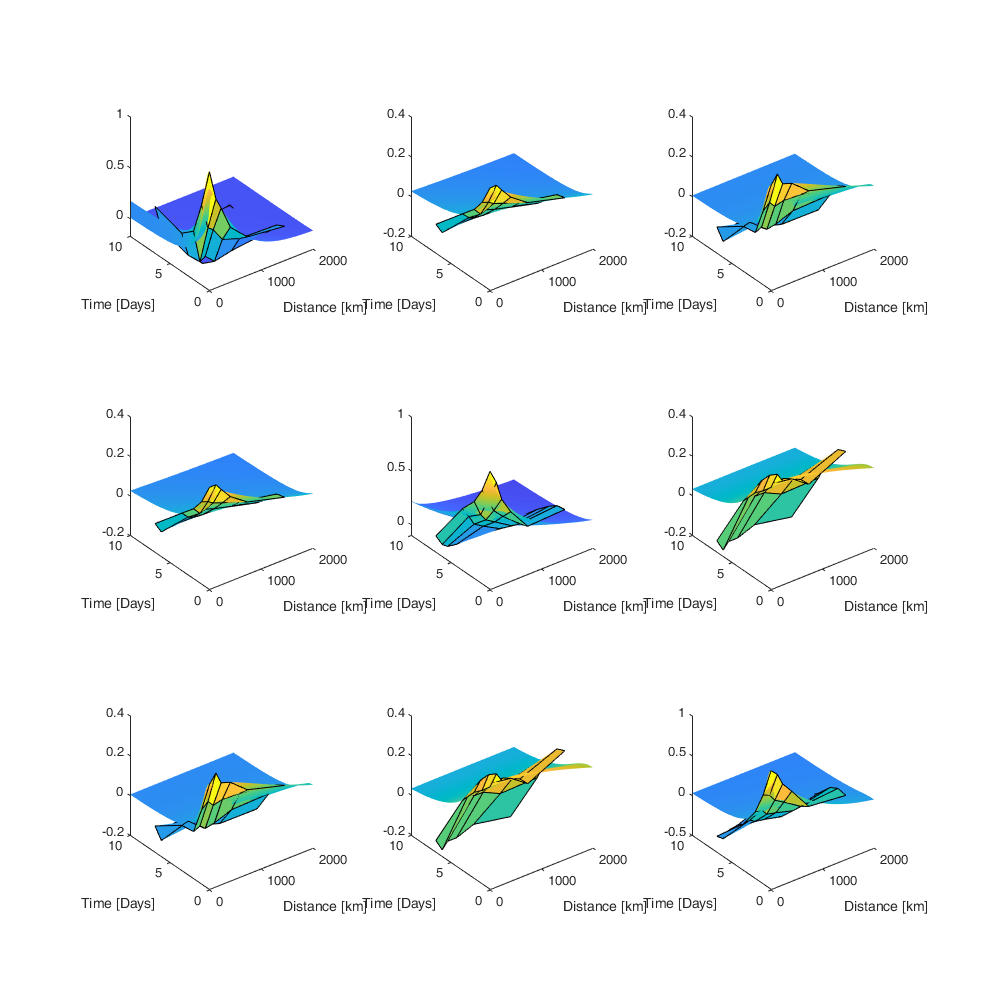

[tmpD,tmpT] = meshgrid(cov_d(1):1:cov_d(end),cov_t(1):0.1:cov_t(end));
figure('position',[0 0 1000 1000]);  hold on;
for i_v1=1:size(ampli.A,3)
    for i_v2=1:size(ampli.A,3)
        subplot(size(ampli.A,3),size(ampli.A,3),i_v1+(i_v2-1)*size(ampli.A,3)); hold on
        surf(cov_D_emp, cov_T_emp, cov_emp_grid(:,:,i_v1,i_v2));  xlabel('Distance [km]'); ylabel('Time [Days]');
        s=surf(tmpD,tmpT,ampli.cov.C{i_v1,i_v2}(tmpD, tmpT));
        s.EdgeColor='none'; 
        view(3)
    end
end

## 3. Residual

The second scale is the intra-night. 

Compute the the residual (still containing the curve)

tmp1 = ampli.A(:,:,1);
tmp2 = ampli.A(:,:,2);
tmp3 = ampli.A(:,:,3);
res.R = [data.denst-tmp1(data.dayradar) data.temperature+tmp2(data.dayradar) data.meanwind-tmp3(data.dayradar)];

### 3.1 Trend

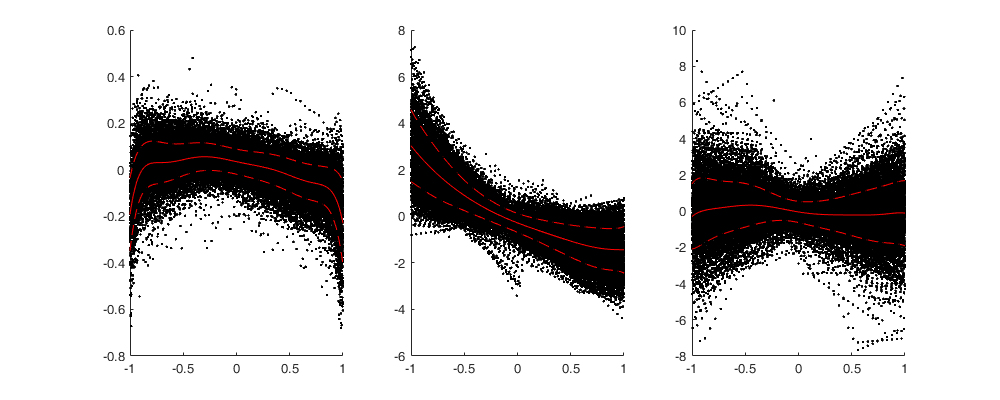

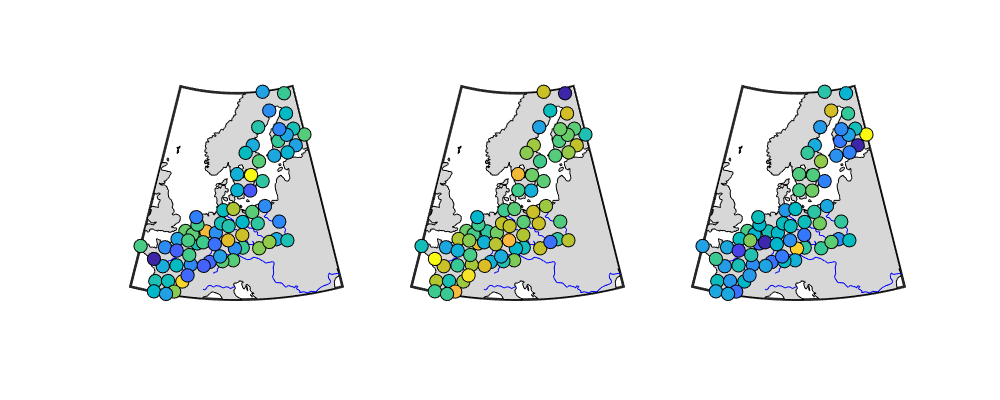

res.apo=8;
res.a = bsxfun(@power,data.NNT,0:res.apo)\res.R;

res.bpo=10;
res.b = bsxfun(@power,data.NNT,0:res.bpo) \ (res.R-bsxfun(@power,data.NNT,0:res.apo)*res.a).^2;

NNT_axis=-1:.01:1;

figure('position',[0 0 1000 400]);
for i_v=1:size(res.R,2)
    subplot(1,3,i_v); hold on;
    plot(data.NNT,res.R(:,i_v),'.k')
    plot(NNT_axis, bsxfun(@power,NNT_axis',0:res.apo)*res.a(:,i_v),'-r');
    plot(NNT_axis, bsxfun(@power,NNT_axis',0:res.apo)*res.a(:,i_v) - sqrt(bsxfun(@power,NNT_axis',0:res.bpo)*res.b(:,i_v)),'--r');
    plot(NNT_axis, bsxfun(@power,NNT_axis',0:res.apo)*res.a(:,i_v) + sqrt(bsxfun(@power,NNT_axis',0:res.bpo)*res.b(:,i_v)),'--r');
end
figure('position',[0 0 1000 400]);
for i_v=1:size(res.Rn,2)
    subplot(1,3,i_v); h=worldmap([min(dclat) max(dclat)], [min(dclon) max(dclon)]);
    setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
    geoshow('landareas.shp', 'FaceColor', [215 215 215]./255); geoshow('worldrivers.shp','Color', 'blue')
    scatterm(dclat,dclon,100,splitapply(@mean,res.R(:,i_v),data.radar),'filled','MarkerEdgeColor','k');%title(tt(i_v))
end

res.Rn = (res.R-bsxfun(@power,data.NNT,0:res.apo)*res.a) ./ sqrt(bsxfun(@power,data.NNT,0:res.bpo)*res.b);

### 3.2. Covariance function 

Built the matrix of distances of the data. Distence (or difference) in lattitude, longitude, time and value. 

Ddist_sm = squareform(pdist([dclat dclon], @lldistkm));

D=table(); 
for i_t=1:numel(ampli.t)
    id = find(data.day==i_t);
    d= table();
    d.Ddist = reshape(Ddist_sm(data.radar(id),data.radar(id)),[],1);
    d.Dtime = reshape(squareform(pdist(data.time(id))),[],1);
    d.Did1 = repmat(id,numel(id),1);
    d.Did2 = repelem(id,numel(id));
    D=[D ; d];
end

Covariance of variables

nancov_res_Rn=nancov(res.Rn)

nancov_res_Rn =     1.0002    0.0593    0.1042
    0.0593    0.9999   -0.0013
    0.1042   -0.0013    0.9986


Covariance on a grid

cov_d=[0 1 150 300 600 1000];
cov_t=[0 .01 .02 .05 .07 .1 .5]; 
[cov_D, cov_T] = meshgrid(cov_d(1:end-1)+diff(cov_d)/2, cov_t(1:end-1));
cov_D_emp=nan(size(cov_D)); 
cov_T_emp = cov_D_emp; 
cov_emp_grid=nan(size(cov_D,1),size(cov_D,2),size(res.Rn,2),size(res.Rn,2));

for i_d=1:numel(cov_d)-1
    id1 = find(D.Ddist>=cov_d(i_d) & D.Ddist<cov_d(i_d+1));
    for i_t=1:numel(cov_t)-1
        id2 = id1(D.Dtime(id1)>=cov_t(i_t) & D.Dtime(id1)<cov_t(i_t+1));
        cov_D_emp(i_t,i_d) = nanmean(D.Ddist(id2)); 
        cov_T_emp(i_t,i_d) = nanmean(D.Dtime(id2));
        for i_v1=1:size(res.Rn,2)
            for i_v2=1:size(res.Rn,2)
                cov_emp_grid(i_t,i_d,i_v1,i_v2)= mean(res.Rn(D.Did1(id2),i_v1) .* res.Rn(D.Did2(id2),i_v2));
            end
        end
    end
end

The covariance function is fitted with a nugget and a Gneiting model. 

Gneiting_fit = @(parm) parm(1)*(cov_D_emp==0 & cov_T_emp==0) + parm(2)*(cov_D_emp==0) + parm(3).*Gneiting(cov_D_emp,cov_T_emp,parm(4),parm(5),parm(6),parm(7),parm(8));
parm0=[0 .5 .5 500 5 .5 .5 .5 ];
parm_min=[-.1 -.1 -.1 .0001 0 0 0 0 ]';
res.cov.C=cell(size(res.Rn,3));
res.cov.parm=nan(size(res.Rn,3),size(res.Rn,3),8);
for i_v1=1:size(res.Rn,2)
    for i_v2=1:size(res.Rn,2)
        parm_max=max([nancov_res_Rn(i_v1,i_v2) nancov_res_Rn(i_v1,i_v2) nancov_res_Rn(i_v1,i_v2) 3000 10 1 1 1 ]',0);
        rmse = @(parm) sum(sum(  ( 1000.*abs(Gneiting_fit(parm) - cov_emp_grid(:,:,i_v1,i_v2)) ) ));
        res.cov.parm(i_v1,i_v2,:) = fmincon(rmse,parm0,[],[],[1 1 1 0 0 0 0 0],nancov_res_Rn(i_v1,i_v2),parm_min,parm_max,[],optimoptions('fmincon','Display','off'));% ,optimset('PlotFcn',@optimplotfval)
        res.cov.C{i_v1,i_v2} = @(D,T) res.cov.parm(i_v1,i_v2,1)*(D==0 & T==0) + res.cov.parm(i_v1,i_v2,2)*(D==0) + res.cov.parm(i_v1,i_v2,3).*Gneiting(D,T,res.cov.parm(i_v1,i_v2,4),res.cov.parm(i_v1,i_v2,5),res.cov.parm(i_v1,i_v2,6),res.cov.parm(i_v1,i_v2,7),res.cov.parm(i_v1,i_v2,8));
    end
end

Illustration of the fitted covariance function

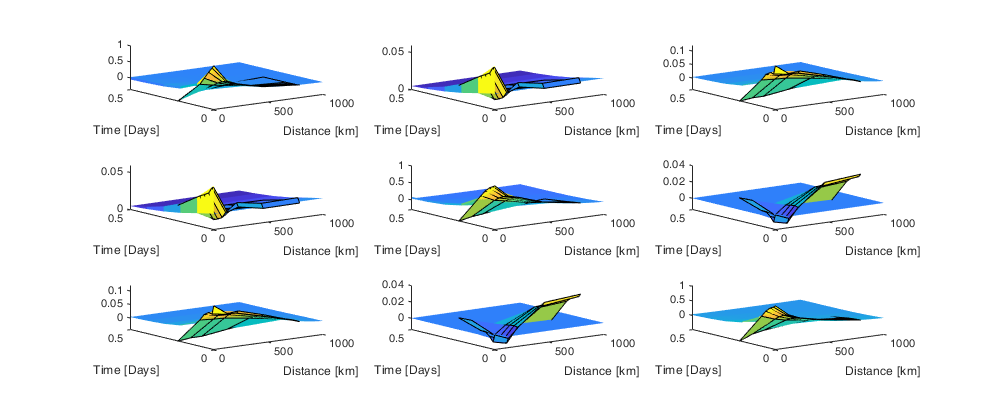

[tmpD,tmpT] = meshgrid(cov_d(1):1:cov_d(end),cov_t(1):0.1:cov_t(end));
figure('position',[0 0 1000 400]);  hold on;
for i_v1=1:size(res.Rn,2)
    for i_v2=1:size(res.Rn,2)
        subplot(3,3,i_v1+(i_v2-1)*3); hold on
        surf(cov_D_emp, cov_T_emp, cov_emp_grid(:,:,i_v1,i_v2));  xlabel('Distance [km]'); ylabel('Time [Days]');
        s=surf(tmpD,tmpT,res.cov.C{i_v1,i_v2}(tmpD, tmpT));
        s.EdgeColor='none'; 
        view(3)
    end
end

## 4. Save

Save the parameters of the model. 

save('data\Density_inference_wind_temp','data','ampli','res','pow_a');